# Flux Balance Analysis (FBA)

## Author(s): **Vanja Vlasov, **Marouen Ben Guebila, **Systems Biochemistry Group, LCSB, University of Luxembourg, **

## **Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg** 

##  Reviewer(s): Ines Thiele, **Systems Biochemistry Group, LCSB, University of Luxembourg**

## **Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg** 

## INTRODUCTION

Flux balance analysis (FBA), one of the most used modelling approaches for metabolic systems, evaluates the metabolic flux distribution [1]. 

Applications of FBA for molecular systems biology include prediction of the growth rates, uptake rates, knockout lethality and product secretion. In FBA, the solution space is constrained by the assumption of a steady-state, under which each internal metabolite is consumed at the same rate as it is produced.

For the quantitative estimation of the metabolic fluxes, linear programming (LP) can be used to solve the stoichiometric matrix for a given objective function under different constraints. The constraints of the problem depict the space of all eligible possibilities from which an optimal solution can be selected. 


$$\begin{array}{ll}
\min\limits _{v} & \ c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $$c\in\Re^{n}$$ is a parameter vector that linearly combines one or more reaction fluxes to form what is termed the objective function,  and where a $$b_{i}<0$$, or  $$b_{i}>0$$, represents some fixed output, or input, of the ith molecular species. $$S\in\Re^{m\times n}$$ is a stoichiometric matrix for $$m$ molecular species and $$n$ reactions, and $$b$ is a vector of known metabolic exchanges. The output of FBA is a particular flux distribution, $$v$ , which maximises or minimises the objective function and stands between upper and lower bounds, $$u$ and $$l$, respectively.

There are multiple different variants of FBA which will be discussed here:

- **Standard FBA**

- **Sparse FBA**

- **Metabolite dilution FBA (mdFBA)**

- **Geometric FBA**

- **Parsimonious enzyme usage Flux Balance Analysis (pFBA)**

- **Dynamic FBA**

- **Relax FBA**

- **Flux enrichment analysis (FEA)**

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


The present tutorial can run with `'glpk``'` package, which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the `'gurobi'` package. For detail information, refer to the solver installation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md)

## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
filename = '2017_04_28_Recon3d.mat';
load([pathModel, filename])
model = modelRecon3model;
clear modelRecon3model

In this tutorial, the provided model is a generic model of the human cellular metabolism, Recon 3D [2]. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body.

## Standard FBA

Standard FBA allows prediction of a cellular objective for a given set of constraints. These constraints can include e.g. uptake and release limits, or minimal and maximal reaction fluxes.

## TIMING

The time to determine a FBA solution depends on the size of the genome-scale model and is commonly less than a second for a medium sized model.

- *Calculating maximal ATP energy production under aerobic condition *

For each new simulation, the original model will be copied to a new variable. This preserves the constraints of the original model and allows to perform simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

modelaerobic = model;

The ATP demand reaction, i.e., `DM_atp_c_ `within the model is a reaction that involves hydrolysis of ATP to ADP, Pi and proton in the cytosol. 

 printRxnFormula(model, 'DM_atp_c_');

We will set this reaction as our objective with the `'changeObjective'` command. Maximising the flux through this reaction will result in the remaining network producing a maximal amount of ATP (up to the limit of the reaction).

modelaerobic = changeObjective (modelaerobic, 'DM_atp_c_');

The glucose and oxygen, in this case, are provided in high amounts for calculating the flux through ATP demand. 

The `'changeRxnBounds' `command changes the lower ('`l`'), upper ('`u`'), or both the bounds ('`b`') for the specified reaction. Here we fix the glucose uptake to 20 $\mu$mol/min/g of proteins and allow a maximal uptake of oxygen of 1000 $\mu$mol/min/g of proteins. The oxygen uptake flux is basically unconstrained. 

modelaerobic = changeRxnBounds (modelaerobic, 'EX_glc_D[e]', -20, 'l');
modelaerobic = changeRxnBounds (modelaerobic, 'EX_o2[e]', -1000, 'l');

The `optimizeCbModel()` calculates one of the optimal solutions within the defined solution space, wherein, the output can be either maximum or minimum flux through the defined objective, whichever is desired. In the above example, the maximal flux through the `DM_atp_c_` is desired. 

FBAaerobic = optimizeCbModel (modelaerobic, 'max')

## ANTICIPATED RESULTS

When oxygen and all external and internal carbon sources are provided and open in the model of the human cell metabolism, the flux through ATP demand reaction is high 1000 $\mu$mol/min/g of proteins. 

## TROUBLESHOOTING

If there are multiple energy sources available in the model; Specifying more constraints is necessary. If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
idx=strmatch('Exchange/demand reaction',model.subSystems);

DM_atp_c_	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 


c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end


FBAaerobic =            x: [10600×1 double]
           f: 1000
           y: [5835×1 double]
           w: [10600×1 double]
        stat: 1
    origStat: 'OPTIMAL'
      solver: 'gurobi'
        time: 0.1287
           v: [10600×1 double]


modelalter = model;
modelalter = changeRxnBounds(modelalter, uptakes, 0, 'b');
modelalter = changeRxnBounds(modelalter, 'EX_HC00250[e]', -1000, 'l');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes = model.rxns(selUpt);
% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
% subuptakeModel = extractSubNetwork(model, uptakes);
% hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'l');

- *Calculating maximum ATP energy production** under anaerobi**c conditi**on*

modelanaerobic = modelalter;
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_glc_D[e]',-20,'l');
modelanaerobic = changeRxnBounds (modelanaerobic, 'EX_o2[e]', 0, 'l');
modelanaerobic = changeObjective(modelanaerobic,'DM_atp_c_');
FBAanaerob = optimizeCbModel(modelanaerobic,'max')

## ANTICIPATED RESULTS

Comparing to the aerobic condition, anaerobic condition with only glucose as an energy source has reduced flux through ATP demand (40 $\mu$mol/min/g of proteins), signifying the need to oxygen to run the oxidative phosphorylation.

## Sparse FBA

Sparse modelling finds the relatively small number of most predictive variables in high-dimensional data sets. Sparse FBA minimises the number of reactions by keeping same maximal objective.


$$\begin{array}{ll}
\min\limits _{v} & \ \\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,\\
& c^{T}v=\rho^*
\end{array}$$


where the last constraint is optional and represents the requirement to satisfy an optimal objective value $\rho^*$ derived from any solution to a FBA problem. This approach is used to check for minimal sets of reactions that either should be active or should not be active in a flux balance model that is representative of a biochemical network.

% [vSparse, sparseRxnBool, essentialRxnBool]  = sparseFBA(model, osenseStr,...
%  checkMinimalSet, checkEssentialSet, zeroNormApprox)

As an optional input there are different appoximation types of zero-norm (only available when `minNorm = 'zero'`). Default is `cappedL1`.

% Other types of zero-norm:
%  * 'cappedL1' : Capped-L1 norm
%  * 'exp'      : Exponential function
%  * 'log'      : Logarithmic function
%  * 'SCAD'     : SCAD function
%  * 'lp-'      : :math:`L_p` norm with :math:`p < 0`
%  * 'lp+'      : :math:`L_p` norm with :math:`0 < p < 1`
%  * 'l1'       : L1 norm
%  * 'all'      : try all approximations and return the best result

## TIMING

The time to determine a `sparseFBA()` solution depends on the size of the genome-scale model and is taking from $<1$ second for a 1,000 reaction model, to $<2$ seconds for a model with more than 10,000 reactions.

modelspar = modelalter;
modelspar = changeRxnBounds(modelspar, 'EX_glc_D[e]',-20,'l');
modelspar = changeRxnBounds (modelspar, 'EX_o2[e]', 0, 'l');
modelspar = changeObjective(modelspar, 'DM_atp_c_');
[vSparse, sparseRxnBool, essentialRxnBool] = sparseFBA(modelspar, 'max');

FBAanaerob =            x: [10600×1 double]
           f: 40.0000
           y: [5835×1 double]
           w: [10600×1 double]
        stat: 1
    origStat: 'OPTIMAL'
      solver: 'gurobi'
        time: 0.1049
           v: [10600×1 double]


## ANTICIPATED RESULTS

Commonly, a sparse FBA solution will have much smaller number of active reactions comparing standard FBA on the same model with same objective function.

Additional outputs of the `sparseFBA` function are `sparseRxnBool `and `essentialRxnBool`, which return vectors with 1 and 0's, with sparse and essential reactions respectively.

Display the sparse flux solution, but only the non-zero fluxes.

for i=1:length(vSparse)
    if vSparse(i)~=0
        fprintf('%10d \t %s\n', vSparse(i), modelspar.rxns{i})
    end
end

csense is not defined. We assume that all constraints are equalities.


---FBA


Obj =40


|vFBA|_0 =1414


Comp. time =0.34


---Non-convex approximation---
40 = sparse LP objective.


Error ||c^T*v - f*||^2=0


83 of these are heuristically minimal rxns.
83 of these are essential rxns.


## Metabolite dilution flux balance analysis (mdFBA)

This is a variant of FBA for predicting metabolic flux distributions by accounting for growth-associated dilution of all metabolites in a context-dependent manner [3]. A solution from `mdFBA()` supports, that all metabolites used in any reaction of the solution can either be produced by the network or taken up from the surrounding medium.

## TIMING

Since this is a MIXED Integer Problem it can take a long time to solve.

- *Calculating ATP energy production under aerobic condition with the mdFBA*

In this function, there is an optional output `newActives`, that represent reactions that are only active in this analysis.

modelmd = model;
modelmd = changeRxnBounds(modelmd, 'EX_glc_D[e]',-20,'l');
modelmd = changeRxnBounds (modelmd, 'EX_o2[e]', 0, 'l');
modelmd = changeObjective(modelmd, 'DM_atp_c_');


-2.666667e+01 	 4ABUTtm


-2.666667e+01 	 ABTArm


4.444444e+00 	 AKGDm


-1.111111e+01 	 AKGt4_3


-4.444444e+00 	 ALATA_L


4.444444e+00 	 CITtam


8.888889e+00 	 DNDPt18m


8.888889e+00 	 FADH2tx


-8.888889e+00 	 FADtx


1.111111e+01 	 FOLt2


4.444444e+00 	 FUMtm


2.222222e+01 	 G3PD2m


1.777778e+01 	 GCC2am


1.777778e+01 	 GCC2bim


1.777778e+01 	 GCC2cm


2.000000e+01 	 GLCt1r


4.444444e+00 	 GLUt2m


1.777778e+01 	 GLYtm


2.222222e+01 	 H2CO3Dm


-4.444444e+00 	 H2Otm


1.777778e+01 	 HPYRRy


-1.777778e+01 	 Htx


2.222222e+01 	 PCm


-2.222222e+01 	 SUCD1m


-4.444444e+00 	 SUCOASm


1.777778e+01 	 THFtm


1.777778e+01 	 TRIOK


-8.888889e+00 	 URIDK2m


-3.555556e+01 	 EX_HC00250[e]


1.777778e+01 	 r0027


2.222222e+01 	 r0081


1.777778e+01 	 r0160


-2.666667e+01 	 r0178


-3.555556e+01 	 r0193


2.000000e+01 	 r0280


2.000000e+01 	 r0355


8.888889e+00 	 r0818


1.777778e+01 	 r0822


-1.777778e+01 	 r0838


8.888889e+00 	 r0853


-3.555556e+01 	 r0940


2.666667e+01 	 r1144


2.222222e+01 	 r1434


4.444444e+00 	 r2472


-8.888889e+00 	 RE1519X


8.888889e+00 	 RE3347C


1.777778e+01 	 GLYSNAT5tc


4.444444e+00 	 DHAPtc


1.777778e+01 	 DM_Lcystin


-1.111111e+01 	 FOLOAT1tc


4.444444e+00 	 r0202m


-2.222222e+01 	 MALOAtm


-1.777778e+01 	 MLTHFtm


2.222222e+01 	 DM_akg[c]


-1.777778e+01 	 ASPTA


4.000000e+01 	 DM_atp_c_


5.777778e+01 	 ENO


2.000000e+01 	 FBA


-4.444444e+00 	 FUM


-2.666667e+01 	 G3PD1


5.777778e+01 	 GAPD


-1.777778e+01 	 GHMT2r


-5.111111e+01 	 H2Ot


2.000000e+01 	 PGI


-5.777778e+01 	 PGK


-5.777778e+01 	 PGM


2.000000e+01 	 TPI


8.888889e+00 	 URIDK3


1.777778e+01 	 GLYt2r


-4.444444e+00 	 MDH


2.000000e+01 	 PFK


3.777778e+01 	 PYK


-1.777778e+01 	 r0392


2.666667e+01 	 GGTe_1


3.555556e+01 	 CYSGLYPTASEe_1


-2.666667e+01 	 EX_CE5026[e]


-8.888889e+00 	 EX_5cysgly34dhphe[e]


3.555556e+01 	 EX_CE1261[e]


8.888889e+00 	 HMR_3321


1.777778e+01 	 HMR_3831


4.444444e+00 	 HMR_4957


-2.000000e+01 	 EX_glc_D[e]


2.666667e+01 	 DM_4abut[c]


[sol, newActives] = mdFBA(modelmd)

## TROUBLESHOOTING

When a model does not have a feasible solution, we are adding an input:  `'getInvalidSolution', true`.

clear modelmd
modelnosol = modelalter;
modelnosol = changeObjective(modelnosol, 'DM_atp_c_');
[sol, newActives] = mdFBA(modelnosol,  'getInvalidSolution', true)

If we run the same FBA (objective function and constraints are the same) many times or using different LP logarithm, each time we may get different fluxes for each reaction. That means we could possibly have different sets of `'x'` values (fluxes of the reactions) and still get the same objective function value `'f'`. Therefore, in a case where we need to compare flux changes between two conditions, some unique values of `'x'` are needed.

This issue can be solved with the `geometricFBA()`, where method provides a standard, central, reproducible solution; or with the `pFBA()`, where results are minimal fluxes through the model, with a classification of each gene by how it contributes to the optimal solution.

## Geometric FBA

The geometric FBA solves the smallest frame that contains all sets of optimal FBA solutions and posts a set of multiple linear programming problems [4].

This variant of the FBA with each applied iteration, reduce by the algorithm the permissible solution space. After a finite number of iterations resolves one single solution of the flux distribution.

% USAGE:
% flux = geometricFBA(model, varargin)

sol =          obj: 1000
      solver: 'gurobi'
        stat: 1
    origStat: 'OPTIMAL'
        time: 60.9957
        full: [10600×1 double]


newActives =     '10FTHF5GLUtl'
    '10FTHFtl'
    '11DOCRTSTRNtr'
    '24NPHte'
    '25HVITD2tin_m'
    '25HVITD3tin_m'
    '2OXOADOXm'
    '2OXOADPTm'
    '34DHPLACOX_NADP_'
    '3AIBTm'
    '3HAO'
    '3HBCDm'
    '3MOBt2im'
    '3SALAOX'
    '3SALATAi'
    '3SALATAim'
    '4HDEBRISOQUINEte'
    '4MTOLBUTAMIDEte'
    '4NPHte'
    '5FTHFt2'
    '5HOMEPRAZOLEte'
    '6DHFtl'
    '6HTSTSTERONEtr'
    'ABUTt4_2_r'
    'ACACtx'
    'ACCOAgt'
    'ACCOAtr'
    'ACGALFUCGALACGALFUC12GAL14ACGLCGALGLUSIDEte'
    'ACGALFUCGALACGALFUCGALACGLCGAL14ACGLCGALGLUSIDEte'
    'ACGALK'
    'ACGAMK'
    'ACGAMPM'
    'ACHEe'
    'ACNACNGAL14ACGLCGALGLUSIDEte'
    'ACNACNGALGBSIDEtg'
    'ACNAM9PL'
    'ACNAM9PL2'
    'ACNAMtn'
    'ACNGALACGLCGAL14ACGLCGALGLUSIDEte'
    'ACNMLr'
    'ACOAO7p'
    'ACOX22x'
    'ACOX2x'
    'ACRNtm'
    'ACSRTNMT'
    'ACtg'
    'ACTNMO'
    'ADCim'
    'ADNCYC'
    'ADSK'
    'AFLATOXINte'
    'AHCYStr'
    'AKR1D2'
    'ALCD21_D'
    'ALOX52'
    'AMACR2p'
    'AMACRp

## TIMING

The time to determine a geometric FBA solution depends on the size of the genome-scale model and the number of iterations. For a model with more than 10,000 reactions and 3 iterations takes $\ge 30$minutes.

modelgeo = modelalter;
modelgeo = changeRxnBounds(modelgeo, 'EX_glc_D[e]',-20,'l');
modelgeo = changeRxnBounds (modelgeo, 'EX_o2[e]', 0, 'l');
modelgeo = changeObjective(modelgeo, 'DM_atp_c_');

sol =         cont: []
         int: []
         obj: []
      solver: 'gurobi'
        stat: 0
    origStat: 'INFEASIBLE'
        time: 0.3095
        full: []



newActives =

  0×0 empty cell array



FBAgeo = geometricFBA (modelgeo);

Display the unique fluxes from reactions, that are non-zero in the geometric FBA solution.

for i=1:length(FBAgeo)
    if FBAgeo(i)~=0
        fprintf('%10d \t %s\n', FBAgeo(i), modelgeo.rxns{i})
    end
end

# reactions:	10600

iteration #0	@ 4:05 PM
fixed:		8110
@ zero:		8107

iteration #1	@ 4:32 PM
fixed:		10566
@ zero:		10506

iteration #2	@ 4:40 PM
fixed:		10596
@ zero:		10506

iteration #3	@ 4:40 PM
fixed:		10600
@ zero:		10506



## TROUBLESHOOTING

 When the algorithm has convergence problems, change one of the optional inputs, `flexRel`, into e.g. `1e-3`. The default is 0 when there is flexibility to flux bounds

Enter the optional parameters as parameter name followed by parameter value: 

i.e. `flux = geometricFBA(model, 'epsilon', 1e-9)`

## Parsimonious enzyme usage Flux Balance Analysis (pFBA)

The pFBA method was developed to achieve higher flux levels when more enzymes are required [5]. 

After performing the FBA to find the optimal value for the objective function, pFBA gets the answer of an another linear program to determine the flux distribution that minimises the total flux through all metabolic reactions in the model.

## TIMING

The time to determine a pFBA solution depends on the size of the genome-scale model and is taking from $<1$ minute for a 1,000 reaction model, to 5 minutes for a model with more than 10,000 reactions.

The function is:

% [GeneClasses RxnClasses modelIrrevFM] = pFBA(model, varargin)

Where 'varagin' includes required inputs:

% * 'geneoption' - 0 = minimize the sum of all fluxes in the network,
%                   1 = only minimize the sum of the flux through
%                   gene-associated fluxes (default),
%                   2 = only minimize the sum of the flux through
%                   non-gene-associated fluxes
%

-2.666667e+01 	 4ABUTtm


-2.666667e+01 	 ABTArm


4.444444e+00 	 AKGDm


-1.111111e+01 	 AKGt4_3


-4.444444e+00 	 ALATA_L


1.111111e+00 	 ASPGLUm


-1.111111e+00 	 ASPTAm


1.111111e+00 	 CITtam


8.888889e+00 	 DNDPt18m


8.888889e+00 	 FADH2tx


-8.888889e+00 	 FADtx


1.111111e+01 	 FOLt2


-1.666667e+00 	 FUMm


2.222222e+00 	 FUMtm


2.111111e+01 	 G3PD2m


8.888889e+00 	 GCC2am


8.888889e+00 	 GCC2bim


8.888889e+00 	 GCC2cm


8.888889e+00 	 GCCam


8.888889e+00 	 GCCbim


8.888889e+00 	 GCCcm


2.000000e+01 	 GLCt1r


-1.111111e+00 	 GLUDxm


3.333333e+00 	 GLUt2m


1.777778e+01 	 GLYtm


2.222222e+01 	 H2CO3Dm


-7.222222e+00 	 H2Otm


1.777778e+01 	 HPYRRy


-1.777778e+01 	 Htx


2.222222e+01 	 PCm


-2.222222e+01 	 SUCD1m


-4.444444e+00 	 SUCOASm


1.777778e+01 	 THFtm


1.777778e+01 	 TRIOK


-8.888889e+00 	 URIDK2m


-3.555556e+01 	 EX_HC00250[e]


1.777778e+01 	 r0027


2.222222e+01 	 r0081


1.777778e+01 	 r0160


1.000000e+01 	 r0165


-2.666667e+01 	 r0178


1.000000e+01 	 r0191


-3.555556e+01 	 r0193


1.000000e+01 	 r0280


1.000000e+01 	 r0355


8.888889e+00 	 r0818


1.833333e+01 	 r0822


-1.666667e+01 	 r0838


8.888889e+00 	 r0853


-3.555556e+01 	 r0940


2.666667e+01 	 r1144


2.222222e+01 	 r1434


6.666667e+00 	 r2472


-8.888889e+00 	 RE1519X


8.888889e+00 	 RE3347C


1.777778e+01 	 GLYSNAT5tc


6.666667e+00 	 DHAPtc


1.111111e+00 	 GLYC3PFADm


1.777778e+01 	 DM_Lcystin


-1.111111e+01 	 FOLOAT1tc


5.555556e+00 	 r0202m


-2.111111e+01 	 MALOAtm


-1.777778e+01 	 MLTHFtm


2.222222e+01 	 DM_akg[c]


-1.777778e+01 	 ASPTA


4.000000e+01 	 DM_atp_c_


5.777778e+01 	 ENO


2.000000e+01 	 FBA


-1.666667e+00 	 FUM


-2.777778e+01 	 G3PD1


5.777778e+01 	 GAPD


-1.777778e+01 	 GHMT2r


-5.111111e+01 	 H2Ot


1.000000e+01 	 HEX1


2.000000e+01 	 PGI


-5.777778e+01 	 PGK


-5.777778e+01 	 PGM


2.000000e+01 	 TPI


8.888889e+00 	 URIDK3


1.777778e+01 	 GLYt2r


-3.333333e+00 	 MDH


1.000000e+01 	 PFK


3.777778e+01 	 PYK


-1.777778e+01 	 r0392


2.666667e+01 	 GGTe_1


3.555556e+01 	 CYSGLYPTASEe_1


-2.666667e+01 	 EX_CE5026[e]


-8.888889e+00 	 EX_5cysgly34dhphe[e]


3.555556e+01 	 EX_CE1261[e]


8.888889e+00 	 HMR_3321


1.888889e+01 	 HMR_3831


1.111111e+00 	 HMR_4957


-2.000000e+01 	 EX_glc_D[e]


2.666667e+01 	 DM_4abut[c]


% * 'map' - map structure from readCbMap.m (no map written if empty)
%
% * 'mapoutname' - File Name for map
%
% * 'skipclass' - 0 = classify genes and reactions (default).
%                 1 = Don't classify genes and reactions. Only return
%                     model with the minimium flux set as upper bound.

Given outputs in this function are:

% OUTPUTS:
% GeneClasses:  Structure with fields for each gene class
% RxnsClasses:  Structure with fields for each reaction class
% modelIrrevFM: Irreversible model used for minimizing flux with
%               the minimum flux set as a flux upper bound

Following example tests the basic solution for minimising the flux of all reactions, while producing energy only from glucose media.

modelp = modelalter;
modelp = changeRxnBounds(modelp, 'EX_glc_D[e]',-20,'l');
modelp = changeRxnBounds (modelp, 'EX_o2[e]', 0, 'l');
modelp = changeObjective(modelp, 'DM_atp_c_');
[GeneClasses RxnClasses modelIrrevFM] = pFBA(modelp,...
    'geneoption', 0, 'skipclass', 1)

netFlux	fluxMeasure 	->	



GeneClasses =

     []




RxnClasses =

     []



modelIrrevFM =                           rxns: {14204×1 cell}
                          mets: {5836×1 cell}
                      metNames: {8425×1 cell}
                   metFormulas: {5835×1 cell}
                            lb: [14204×1 double]
                            ub: [14204×1 double]
                    subSystems: {14204×1 cell}
                      rxnNames: {14204×1 cell}
                 rxnReferences: {14204×1 cell}
                  rxnECNumbers: {14204×1 cell}
                      rxnNotes: {14204×1 cell}
                             S: [5836×14204 double]
                             b: [5836×1 double]
                             c: [14204×1 double]
                           rev: [14204×1 double]
                         genes: {2246×1 cell}
                       grRules: {14204×1 cell}
                     metCharge: [5835×1 double]
                    rxnGeneMat: [14204×2246 double]
                         rules: {14204×1 cell}
                biomassRxnAbb

Display minimal fluxes of the reactions that are required for producing energy only from only glucose media. 

for i=1:length(modelIrrevFM.lb)
    if modelIrrevFM.lb(i)~=0
        fprintf('%10d \t %s\n', modelIrrevFM.lb(i), modelIrrevFM.rxns{i})
    end
end

4.000000e+01 	 DM_atp_c_


1.633333e+03 	 netFlux


## Dynamic FBA

The dynamic FBA is an extension of standard FBA that accounts for cell culture dynamics, implementing both dynamic (nonlinear programming) and static (LP) optimisation of an objective function and applying constraints to the rates of change of flux in addition to the standard FBA constraints [6].

The dynamic FBA method implemented in this function is essentially the same as the method described by Varma A. and B. O. Palsson [7].

ans = 1806

Step number	Biomass
Dynamic FBA analysis in progress ...

No feasible solution - nutrients exhausted. Biomass:	 0.001000


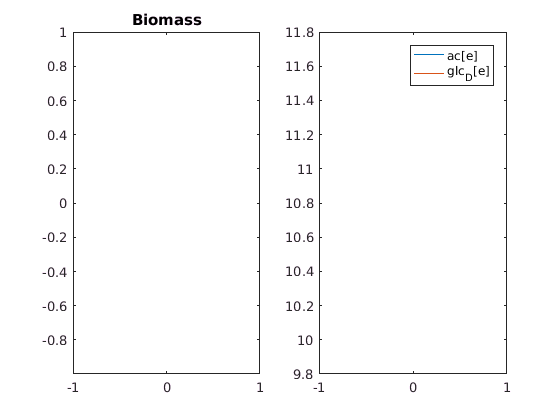

modeldinamic = model;
modeldinamic = changeRxnBounds (modeldinamic, 'EX_glc_D[e]', -20, 'b');
modeldinamic = changeRxnBounds (modeldinamic, 'EX_o2[e]', -1000, 'l');
modeldinamic = changeRxnBounds (modeldinamic, 'EX_ac[e]', -1000, 'l');
smi = {'EX_glc_D[e]' 'EX_ac[e]'}; 
% exchange reaction for substrate in environment

smc = [10.8]; % Glucose, Acetate concentration (all in mM)

Xec = 0.001; % initial biomass
dt = 1.0/100000000000.0; % time steps
time = 1.0/dt; % simulation time

[concentrationMatrix, excRxnNames, timeVec,...
    biomassVec] = dynamicFBA(modeldinamic, smi, smc, Xec, dt, time, smi ); 

## Relax FBA

Find the minimal set of relaxations on bounds and steady-state constraint to make the FBA problem feasible.

modelrelax = modelalter;
FBArel = relaxFBA(modelrelax)

csense is not defined. We assume that all constraints are equalities.


FBArel =     stat: 1
       v: [10600×1 double]
       r: [5835×1 double]
       p: [10600×1 double]
       q: [10600×1 double]


The output `FBArel` contains solution fields, where 

`FBArel.v` is the reaction rate; 

`FBArel.r` is set of reactions that need relaxation on steady state constraints `S*v = b`;

`FBArel.p` is relaxation on lower bound of reactions;

`FBArel.r` is relaxation on upper bound of reactions;

## Flux enrichment analysis (FEA)

The flux enrichment analysis calculates the likelihood that a set of fluxes would belong to a subsystem or pathway.

## TIMING

The time to calculate the FEA is $<1$ second for any size of a model.

modelfea = model;
res = optimizeCbModel(modelfea,'max'); 
% say you are interested in enriching the active reactions
activeReactions = find(res.x) 

activeReactions =      8
    35
    36
    37
    38
    41
    42
    44
    46
    48


% You can also look for e.g. positive/negative/zeros flux reactions,
% that depends pretty much on the question.
% Now you look for the enrichement of reactions per subsystems
resultCell = FEA(modelfea, activeReactions, 'subSystems')

nonZeroInd =     82
    32
    46
    29
    55
    59
     9
    96
     5
    58


resultCell =     'P-value'        'Adjusted P-value'    'Group'                                                 'Enriched set size'    'Total set size'
    [9.6024e-113]    [     7.0098e-111]    'Fatty acid oxidation'                                  [              106]    [           961]
    [5.1810e-112]    [     1.8910e-110]    'Peptide metabolism'                                    [              242]    [           242]
    [ 3.2886e-57]    [      8.0022e-56]    'Xenobiotics metabolism'                                [               64]    [           575]
    [ 1.8208e-45]    [      3.3229e-44]    'Fatty acid synthesis'                                  [                4]    [           239]
    [ 3.2060e-39]    [      4.6808e-38]    'Cholesterol metabolism'                                [                9]    [           242]
    [ 2.2957e-22]    [      2.7930e-21]    'Glycerophospholipid metabolism'                        [               10]    [           165]
    [ 2.5017e-

## REFERENCES 

[1] Orth, J. D., Thiele I., and Palsson, B. Ø.  What is flux balance analysis? *Nat. Biotechnol., 28*(3), 245–248 (2010).

[2] Noronha A., et al. ReconMap: an interactive visualization of human metabolism. *Bioinformatics*., 33 (4): 605-607 (2017).

[3] Benyamini T, et al. Flux balance analysis accounting for metabolite dilution.*Genome Biology*., 11(4):R43 (2010).

[4] Smallbone K., and Simeonidis E. Flux balance analysis: A geometric perspective. *J Theor Biol*., 258: 311-315 (2009).

[5] Lewis N.E, et al. Omic data from evolved E. coli are consistent with computed optimal growth from genome-scale models. 10.1038 (2010).

[6] Mahadevan R., et al. Dynamic Flux Balance Analysis of Diauxic Growth in Escherichia coli. *Biophys J., *83(3):1331-40 (2002).

[7] Varma A. and Palsson, B. Ø. Stoichiometric flux balance models quantitatively predict growth and metabolic by-product secretion in wild-type Escherichia coli W3110. *App Environ Microbiol*., 60(10):3724-31 (1994).